M=10;
n=-n:M;
K=500;
%4 types of window function
tri=unitseq(min(n),M,0).*(1-(M-1-2*n)/(M-1));
x=cos(0.1*pi*n).*tri;
[X,w]=dtft(x,n,K)

X =   -1.2250 + 0.0000i  -1.2225 + 0.0769i  -1.2149 + 0.1535i  -1.2023 + 0.2294i  -1.1848 + 0.3044i  -1.1623 + 0.3780i  -1.1351 + 0.4500i  -1.1032 + 0.5200i  -1.0668 + 0.5878i  -1.0260 + 0.6531i  -0.9810 + 0.7156i  -0.9320 + 0.7749i  -0.8792 + 0.8310i  -0.8228 + 0.8834i  -0.7631 + 0.9321i  -0.7003 + 0.9767i  -0.6347 + 1.0171i  -0.5666 + 1.0531i  -0.4962 + 1.0845i  -0.4239 + 1.1113i  -0.3501 + 1.1333i  -0.2749 + 1.1503i  -0.1987 + 1.1624i  -0.1219 + 1.1695i  -0.0448 + 1.1715i   0.0323 + 1.1684i   0.1091 + 1.1603i   0.1852 + 1.1471i   0.2602 + 1.1290i   0.3340 + 1.1060i   0.4060 + 1.0781i   0.4762 + 1.0456i   0.5440 + 1.0085i   0.6093 + 0.9671i   0.6717 + 0.9214i   0.7311 + 0.8717i   0.7870 + 0.8181i   0.8394 + 0.7610i   0.8878 + 0.7006i   0.9323 + 0.6370i   0.9725 + 0.5707i   1.0082 + 0.5018i   1.0394 + 0.4307i   1.0658 + 0.3577i   1.0874 + 0.2830i   1.1040 + 0.2071i   1.1156 + 0.1302i   1.1222 + 0.0526i   1.1236 - 0.0252i   1.1199 - 0.1031i


w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


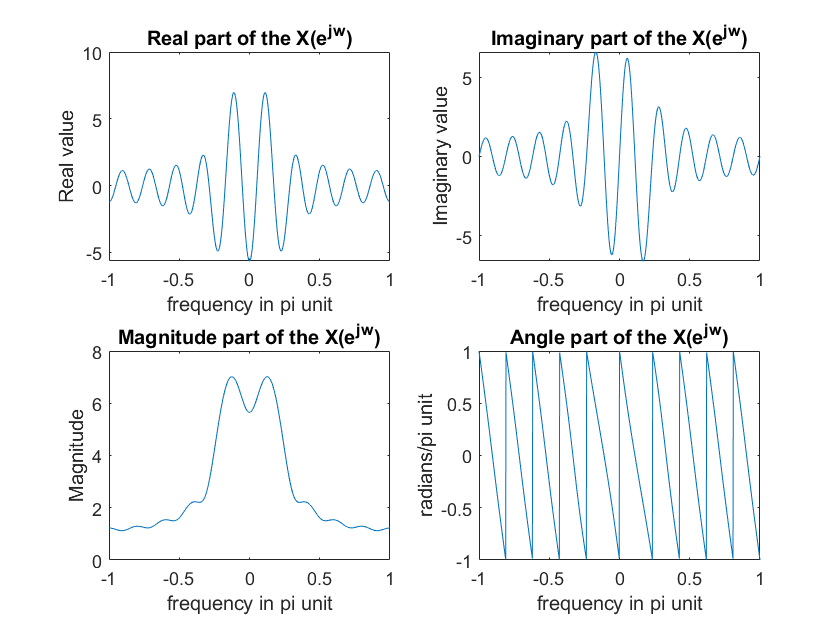

figure("Name",'DTFT')
dfp4(X,w)

Xf=fft(x,length(w))

Xf =   -5.6515 + 0.0000i  -5.6389 + 0.3899i  -5.6014 + 0.7783i  -5.5389 + 1.1635i  -5.4518 + 1.5439i  -5.3404 + 1.9180i  -5.2051 + 2.2843i  -5.0466 + 2.6413i  -4.8654 + 2.9874i  -4.6624 + 3.3214i  -4.4382 + 3.6418i  -4.1938 + 3.9473i  -3.9302 + 4.2367i  -3.6485 + 4.5088i  -3.3498 + 4.7624i  -3.0353 + 4.9967i  -2.7063 + 5.2105i  -2.3640 + 5.4030i  -2.0099 + 5.5734i  -1.6455 + 5.7210i  -1.2720 + 5.8453i  -0.8912 + 5.9457i  -0.5044 + 6.0217i  -0.1133 + 6.0732i   0.2806 + 6.0998i   0.6758 + 6.1014i   1.0706 + 6.0780i   1.4634 + 6.0298i   1.8527 + 5.9568i   2.2370 + 5.8594i   2.6147 + 5.7380i   2.9843 + 5.5929i   3.3444 + 5.4249i   3.6935 + 5.2345i   4.0302 + 5.0225i   4.3533 + 4.7898i   4.6614 + 4.5372i   4.9534 + 4.2658i   5.2281 + 3.9766i   5.4844 + 3.6707i   5.7214 + 3.3494i   5.9381 + 3.0139i   6.1337 + 2.6656i   6.3075 + 2.3057i   6.4588 + 1.9357i   6.5870 + 1.5570i   6.6916 + 1.1712i   6.7724 + 0.7796i   6.8290 + 0.3839i   6.8612 - 0.0145i


figure("Name",'FFT')
% ceil(length(w)/2)
Xf=circshift(Xf,ceil(length(w)/2))% used circular shift by half of length due to reposition

Xf =    1.2243 + 0.0423i   1.2243 - 0.0423i   1.2182 - 0.1266i   1.2061 - 0.2103i   1.1881 - 0.2929i   1.1642 - 0.3740i   1.1345 - 0.4532i   1.0993 - 0.5301i   1.0586 - 0.6042i   1.0127 - 0.6752i   0.9619 - 0.7428i   0.9063 - 0.8065i   0.8464 - 0.8660i   0.7823 - 0.9212i   0.7145 - 0.9715i   0.6432 - 1.0169i   0.5688 - 1.0570i   0.4918 - 1.0917i   0.4125 - 1.1208i   0.3313 - 1.1441i   0.2487 - 1.1615i   0.1650 - 1.1729i   0.0807 - 1.1783i  -0.0037 - 1.1776i  -0.0879 - 1.1709i  -0.1713 - 1.1581i  -0.2536 - 1.1393i  -0.3344 - 1.1147i  -0.4132 - 1.0843i  -0.4895 - 1.0484i  -0.5631 - 1.0070i  -0.6336 - 0.9604i  -0.7004 - 0.9089i  -0.7634 - 0.8527i  -0.8222 - 0.7921i  -0.8765 - 0.7274i  -0.9260 - 0.6589i  -0.9704 - 0.5870i  -1.0096 - 0.5121i  -1.0432 - 0.4346i  -1.0711 - 0.3548i  -1.0933 - 0.2732i  -1.1095 - 0.1901i  -1.1196 - 0.1061i  -1.1237 - 0.0216i  -1.1216 + 0.0631i  -1.1135 + 0.1474i  -1.0992 + 0.2310i  -1.0790 + 0.3134i  -1.0528 + 0.3941i


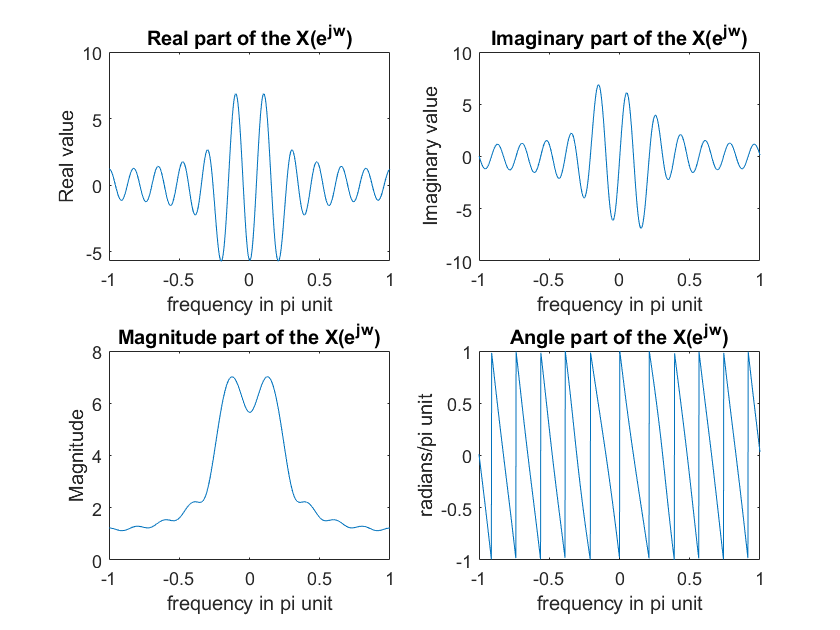

dfp4(Xf,w)